Problem 2.1

ak = [0.1,  0.15, 0.25, 0.26, 0.34, 0.42, 0.25, 0.2, 0.15, 0.1, 0.1, 0.1]; %5 coeffs
b2 = 1;
a2 = [1 -ak];
sys2 = tf(b2,a2,1,"Variable" ,"z^-1") % trasnfer function 

sys2 =
 
                                                                         1
  -----------------------------------------------------------------------------------------------------------------------------------------------
  1 - 0.1 z^-1 - 0.15 z^-2 - 0.25 z^-3 - 0.26 z^-4 - 0.34 z^-5 - 0.42 z^-6 - 0.25 z^-7 - 0.2 z^-8 - 0.15 z^-9 - 0.1 z^-10 - 0.1 z^-11 - 0.1 z^-12
 
Sample time: 1 seconds
Discrete-time transfer function.


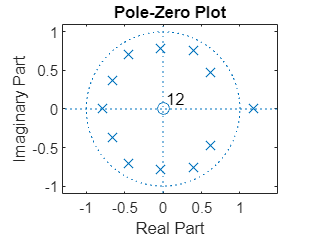

zplane(b2,a2)

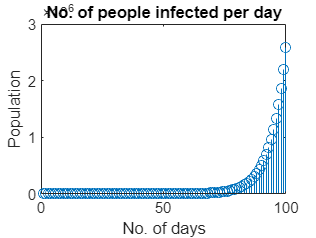

N2 = 1:100;
syms m
m = sym(1);
sol = kroneckerDelta(N2,m);
var = double(sol);
sys3 = filter( b2, a2, var); % impulse response using kronecker delta
stem(N2,sys3)
title("No. of people infected per day")
ylabel("Population")
xlabel("No. of days")

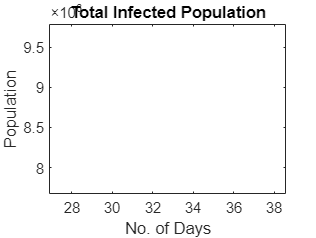

figure;
I2 = filter(b1,a1,sys3); % intergrator filter
stem(I2)
title("Total Infected Population")
ylabel("Population")
xlabel("No. of Days")

figure;
Total_infected_people_2 = I2(end)

Total_infected_people_2 = 1.6996e+07

Problem 2.2

sys3(94)

ans = 9.6058e+05

sys3(95)

ans = 1.1329e+06

% it takes 95 days to reach 1 million